%minimise Error Script
clear;
clc;


input_Image="bean.jpg"; %bean.jpg   %flower.png  %peppers.png  %tomandjerry.png
image=imread(input_Image); 
[k,l,~]=size(image);
m=k*l;
A=repmat(rgb2gray(image),[1,1,3]); % A is greyscale
C=A; % C will be converted into greyscale with colour information

sigma_1=100;   %starting val: 100
sigma_2=100;   %starting val: 100
p=0.5;         %starting val: 0.5
delta=2*10^-4; %starting val: 2*10^-4

percentage=0.005; %out of memory when >0.09 for peppers.png
optimisation_iterations=20; %adjust for number of iterations desired within fminsearch


%%Sampling 
%Uniform grid
grids=round(sqrt(1/percentage),0)

grids = 14

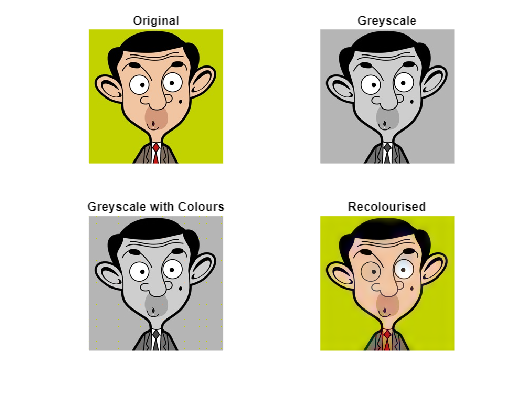

error_initial = 0.0341

for row = 1:grids:k
    for col = 1:grids:l
        C(row,col,:)=image(row,col,:);  
    end
end


%Random points (Sampling)
%i=0;
%random=m*percentage; 
%while i<random
%    row=randi(k,1); 
%    col=randi(l,1); 
%    C(row,col,:)=image(row,col,:);
%    i=i+1;
%end

F_r=C(:,:,1); 
F_g=C(:,:,2); 
F_b=C(:,:,3); 

% to check known original colour
colour_check=(F_r ~= F_g)|(F_g ~= F_b)|(F_b ~= F_r); %ignoring 256 possible 'perfect greyscale' colours that could be part of the original colour info

known=find(colour_check); %locate and find the non zero elements (positions in a 1D matrix/image)

[X,Y]=meshgrid(1:l,1:k);
grey_image=A(:,:,1); 


figure
subplot(2,2,1), imshow(image), title("Original");
subplot(2,2,2), imshow(A), title("Greyscale");
subplot(2,2,3), imshow(C), title("Greyscale with Colours");
subplot(2,2,4)
error_initial=recolourise(image,known,X,Y,A,C,sigma_1,sigma_2,p,delta)

 
 Iteration   Func-count         f(x)         Procedure
     0            1        0.0341477         
     1            5        0.0292072         initial simplex
     2            6        0.0292072         reflect
     3            7        0.0292072         reflect
     4            9        0.0268525         expand
     5           11        0.0239174         expand
     6           12        0.0239174         reflect
     7           14        0.0210408         expand
     8           15        0.0210408         reflect
     9           17        0.0206942         reflect
    10           18        0.0206942         reflect
    11           20        0.0206942         contract outside
    12           21        0.0206942         reflect
    13           23        0.0201765         expand
    14           25        0.0201765         contract inside
    15           26        0.0201765         reflect
    16           28        0.0201765         contract inside
    17           29 

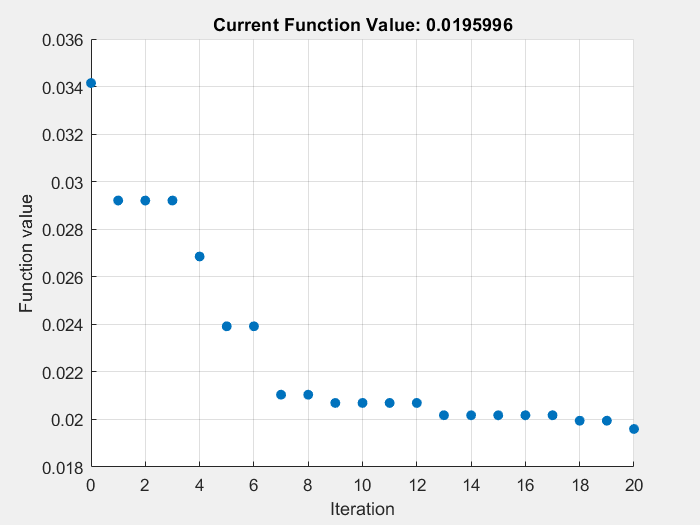



%to ensure constraints, sigma_1, sigma_2, delta>0, use exp/ln... to ensure
%p is between [0,1] use p=1/(1+exp(-c))
initial_param=[log(sigma_1),log(sigma_2),log(p/(1-p)),log(delta)]; %sigma_1, %sigma_2, %p, %delta

global error_iteration lowest_error;
error_iteration=[];
lowest_error=Inf;

options=optimset('Display','iter','MaxIter',optimisation_iterations, 'PlotFcns', @optimplotfval); %select number of iterations desired
optimised=fminsearch(@(x) Error(x, image, known, X, Y, A, C),initial_param,options); %Nelder-Mead Simplex Algorithim



a=optimised(1);
b=optimised(2);
c=optimised(3);
d=optimised(4);

%transform parameters back, ensuring constrants are met
sigma_1_optimised=round(exp(a),0) 

sigma_1_optimised = 392

sigma_2_optimised=round(exp(b),0)

sigma_2_optimised = 151

p_optimised=round(1/(1+exp(-c)),2)

p_optimised = 0.5000

delta_optimised=round(exp(d),5)

delta_optimised = 3.3000e-04

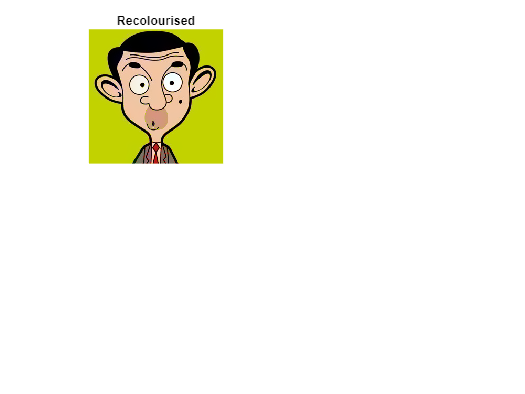

error_optimised = 0.0196


figure
subplot(2,2,1)
error_optimised=recolourise(image,known,X,Y,A,C,sigma_1_optimised,sigma_2_optimised,p_optimised,delta_optimised)


%percentageImprovement=round((error_initial-error_optimised)*100/error_initial,1);
%fprintf('Percentage improvement in error: %f%%\n', percentageImprovement);

%subplot(2,2,2)
%plot(1:length(error_iteration), error_iteration, '-o');
%xlabel('Function Called (n times)');
%ylabel('Error');
%title('Error vs Times Function is Called');
%grid on;